# Actividad 7.1 Waypoints

## Santiago Patricio Gómez Ochoa | A01735171

### Ejercicio 1

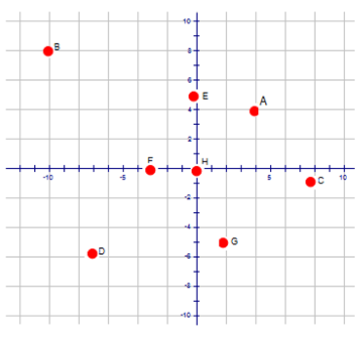

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:92;         % Time array

initPose = [4;4;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [4,4; -10,8; 7.5,-1; -7,-5.5; 0,5; -3,0; 2,-5; 0,0;];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;

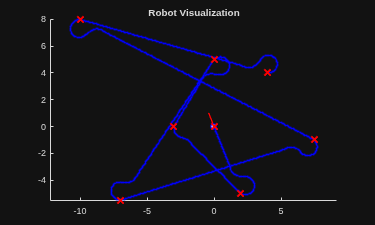


%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);


    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world

    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 

    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);

end

### Ejercicio 2

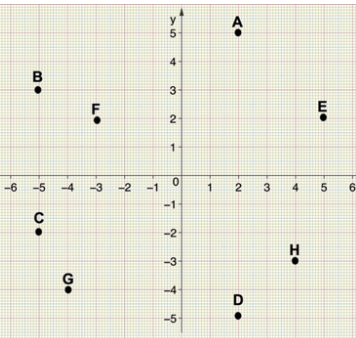

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:27.6;         % Time array

initPose = [-5;3;-0.46];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [-5,3; -3,2; -5,-2; -4,-4; 2,-5; 4,-3; 5,2; 2,5;];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;

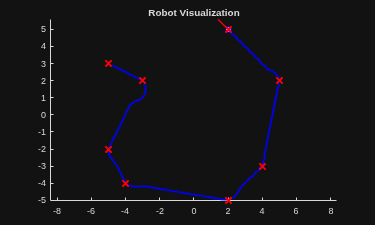


%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);


    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world

    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 

    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);

end

### Ejercicio 3

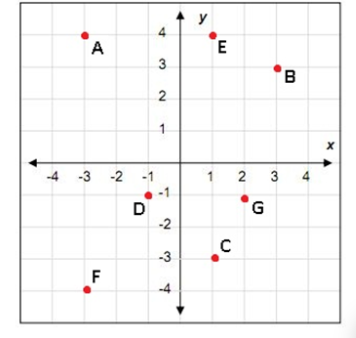

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:20.27;         % Time array

initPose = [-3;4;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [-3,4; 1,4; 3,3; 2,-1; 1,-3; -1,-1; -3,-4;];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;

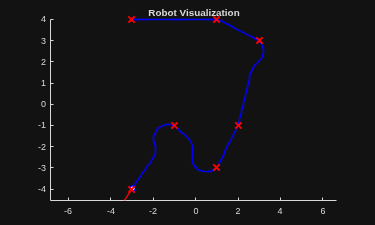


%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);


    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world

    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 

    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);

end

### Ejercicio 4

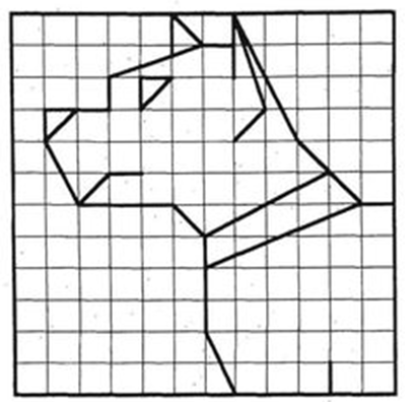

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:171.5; %        % Time array

initPose = [-1;0;pi];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix;
pose(:,1) = initPose;

% Define waypoints
waypoints = [-1,0; -4,0; -3,1; -2,1; -3,1; -4,-0; -5,2; -4,3; -5,3; -5,2; -4,3: -3,3; -3,4; 0,5; -1,6; -1,4; -2,4; -2,3; -1,4; -1,6; 0,5; 1,5; 1,4; 1,6; 2,3; 1,2; 2,3; 1,6; 3,2; 4,1; 5,0; 0,-2; 0,-1; 4,1; 5,0; 6,0; 6,-6; 4,-6; 4,-5; 4,-6; 1,-6; 0,-4; 0,-1; -1,0;];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.4;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 2.5;

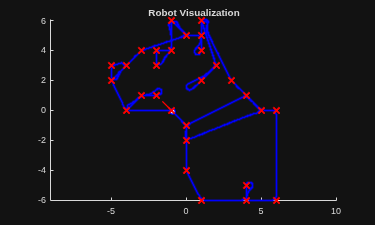


%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);


    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world

    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 

    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);

end

### Ejercicio 5

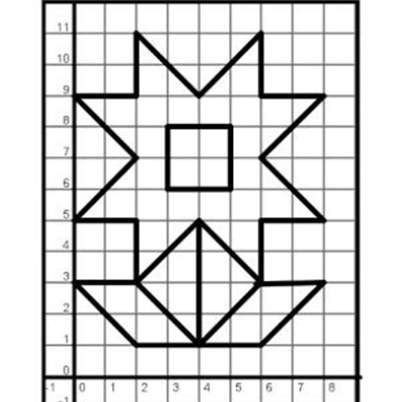

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:167; %        % Time array

initPose = [4;1;pi/4];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix;
pose(:,1) = initPose;

% Define waypoints
waypoints = [4,1; 6,3; 8,3; 6,1; 4,1; 2,3; 0,3; 2,1; 4,1; 4,5; 6,3; 6,5; 8,5; 6,7; 8,9; 6,9; 6,11; 4,9; 2,11; 2,9; 0,9; 2,7; 0,5; 2,5; 2,3; 4,5; 4,6; 5,6; 5,8; 3,8; 3,6; 4,6;];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.39;
controller.DesiredLinearVelocity = 0.4;
controller.MaxAngularVelocity = 4;

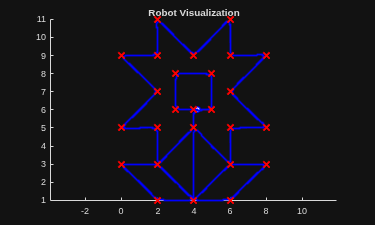


%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);


    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world

    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 

    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);

end

### Ejercicio 6

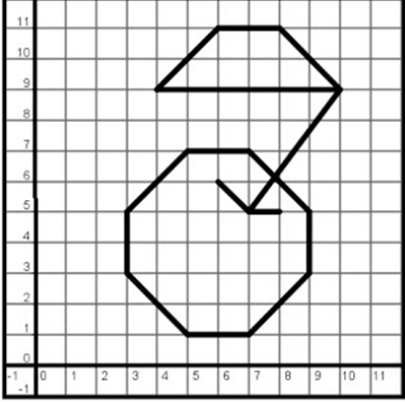

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:110; %        % Time array

initPose = [10;9;pi];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix;
pose(:,1) = initPose;

% Define waypoints
waypoints = [10,9; 4,9; 6,11; 8,11; 10,9; 7,5; 6,6; 7,5; 9,5; 9,3; 7,1; 5,1; 3,3; 3,5; 5,7; 7,7; 9,5; 9,3;];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.39;
controller.DesiredLinearVelocity = 0.4;
controller.MaxAngularVelocity = 4;

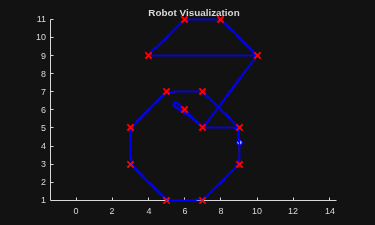


%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);


    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world

    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 

    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);

end

### Conclusión

Nótese que específicamente en las 3 últimas figuras, hay algunas secciones en las que se producen curvas cuando el robot regresa a un punto anteriormente visitado. Esto se debe a que en todo momentto, el robot posee tanto velocidad lineal como angular, con lo cual siempre corrige sus velocides en función a la trayectoria que debe tomar, dada por el lookahead point. Si esta figura se realizara con un sistema a lazo abierto (en el que se especifica manualmente la velocidad angular y lineal que el robot debe tomar en cada tiempo) la imagen podría salir recta al separar sus velocidades en cada instante de tiempo. 